# 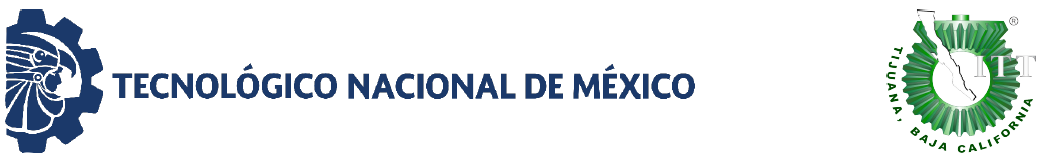

# Proyecto Final.- Sistema Urinario: Síndrome Nefrótico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana,**

**B.C., México**

## Información General

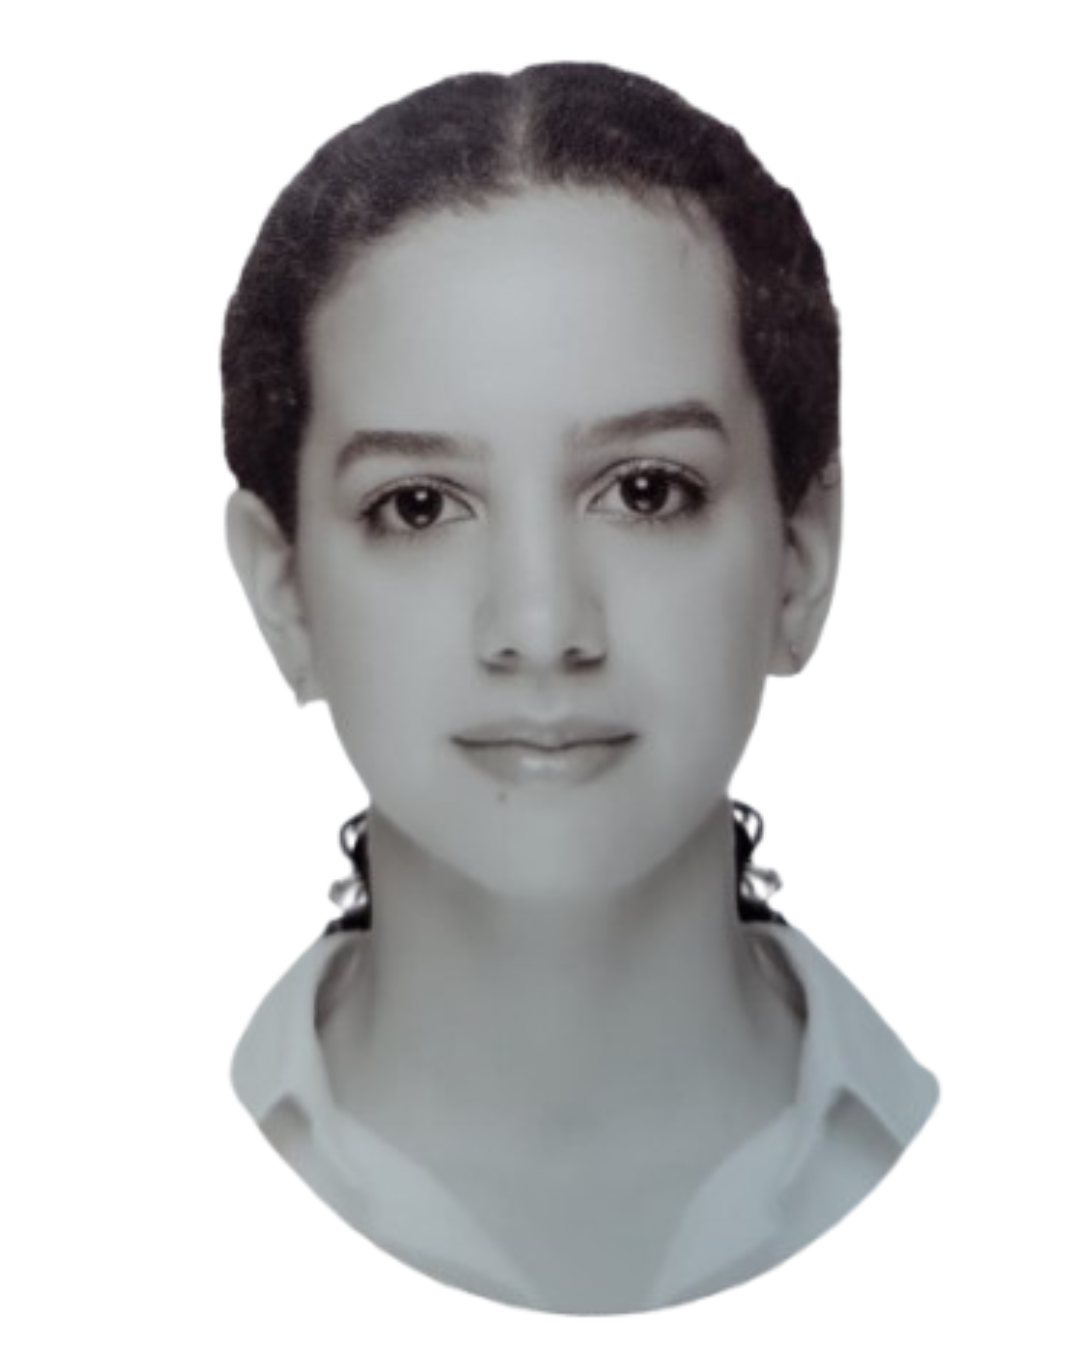

Nombre del alumno:** Jeanette Cubillas Arteaga**

Número de control:** 20212948**

Correo institucional: **l20212948@tectijuana.edu.mx**

Asignatura**: Modelado de Sistemas Fisiológicos**

Docente**: Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos Generales de la Simulación

clc; clear all; close all;
tend='10'; 
file='Sistema';
open_system(file);
parameters.StopTime=num2str(tend);
parameters.Solver='ode15s';

## Respuesta a la Función Sinusoidal

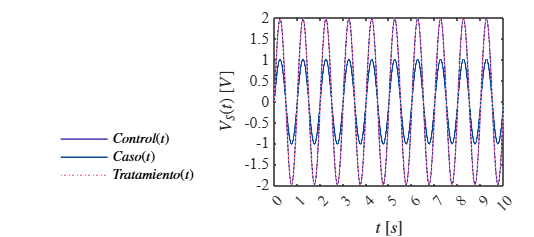

N=sim(file,parameters);
plotsignals(N.t,N.Ve,N.Px,N.Py,N.Pz);

## Función: Respuesta a las señales

function plotsignals(t, Ve, Px, Py, Pz, Signal)
    % Configuración de figura
    fig = figure('Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

    % Colores personalizados
    Morado = [70/255, 53/255, 177/255];
    Verde  = [62/255, 123/255, 39/255];
    Rosa   = [255/255, 116/255, 139/255];
    Azul   = [7/255, 71/255, 153/255];

    % Graficado
    hold on; grid off; box on
    plot(t, Px, 'LineWidth', 1, 'Color', Morado)
    plot(t, Py, 'LineWidth', 1, 'Color', Azul)
    plot(t, Pz, ':', 'LineWidth', 1, 'Color', Rosa)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11)

    L = legend('$Control(t)$','$Caso(t)$','$Tratamiento(t)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'southwestoutside', 'Box', 'off')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_S(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    ylim([-2.,2]); yticks(-2:0.5:2)

    name='simulink.pdf';
    exportgraphics(gcf,name,'ContentType','vector')
end